clear all

## Load the image

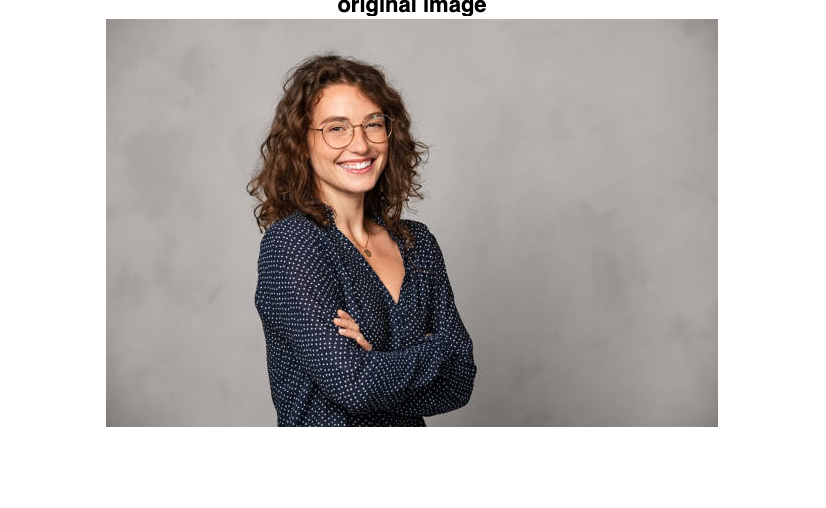

imname = 'portrait.jpeg';
im_all = imread(imname);

% Show original image
figure
imshow(im_all)
title('original image')

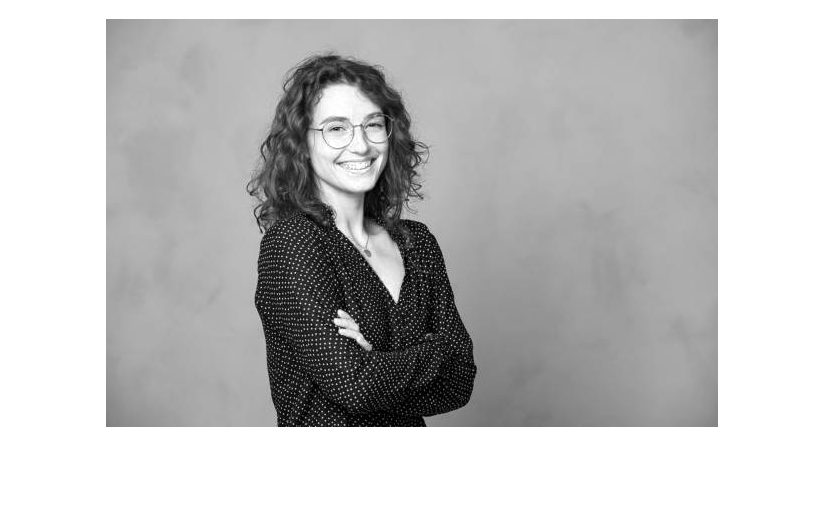

imshow(im_all(:,:,1), [])

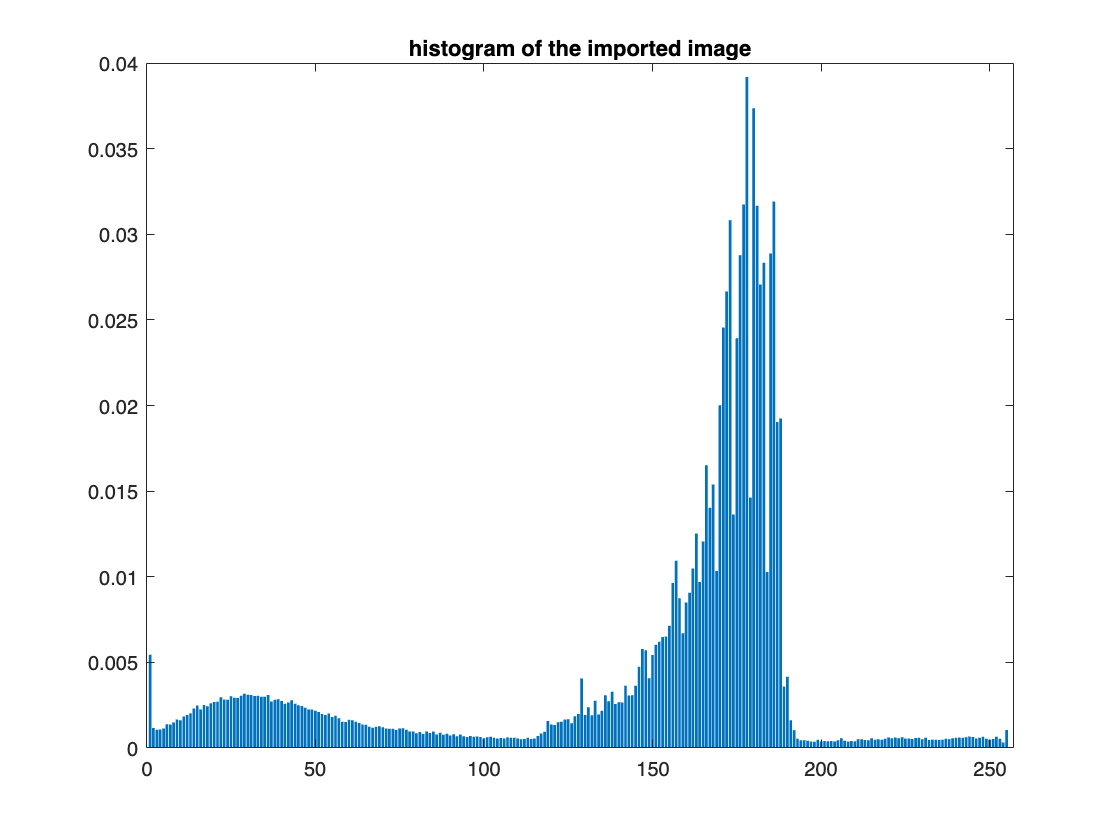

imageSize_original = size(im_all);
im_all = double(im_all);

% Compute the histogram
[h_count,h_cent] = imhist(im_all(:,:,1)./256);
h_prob = h_count./numel(im_all(:,:,1));
figure
bar(h_prob)
title('histogram of the imported image')

## Preprocessing

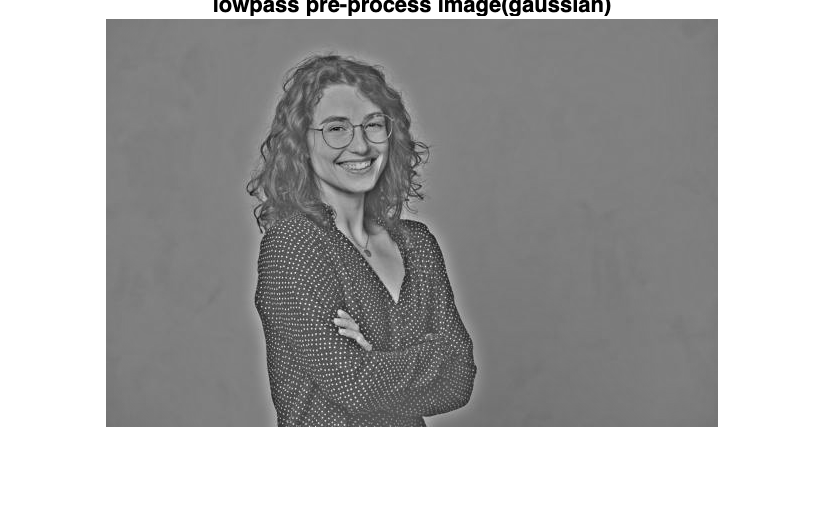

pre_processing = 'lowpass';

im_temp = zeros(imageSize_original);
im_pre_processing_mask = zeros(imageSize_original);
im_pre_processing_mask2 = zeros(imageSize_original);
im_pre_processing = zeros(imageSize_original);

switch pre_processing
    case 'lowpass'
        sigma = 8;
        for i=1:3
            im_temp(:,:,i) = imgaussfilt(im_all(:,:,i),sigma);
            im_pre_processing_mask(:,:,i) = im_all(:,:,i)-im_temp(:,:,i);
        end
        im_pre_processing_mask = mean(im_pre_processing_mask, 3);
        im_pre_processing = im_all + im_pre_processing_mask.* 3;
        figure(4)
        imshow(im_pre_processing(:,:,1),[])
        title('lowpass pre-process image(gaussian)')
    case 'highpass1'
        for i=1:3
            im_pre_processing_mask2(:,:,i) = imfilter(im_all(:,:,i), fspecial('laplacian'));
        end
        im_pre_processing_mask = mean(im_pre_processing_mask2, 3);
        im_pre_processing = im_all - im_pre_processing_mask.* 1;
        figure(4)
        imshow(im_pre_processing(:,:,1),[])
        title('highpass pre-process image(laplacian)')
    case 'highpass2' % not working
        hp = (1./9).* [-1 -1 -1; -1 8 -1; -1 -1 -1];
        for i=1:3
            % im_pre_processing_mask2(:,:,i) = imfilter(im_all(:,:,i), hp);
            im_pre_processing(:,:,i) = filter2(hp,im_all(:,:,i)); 
        end
        % im_pre_processing_mask = mean(im_pre_processing_mask2, 3);
        % im_pre_processing = im_all - im_pre_processing_mask.* 1;
        figure(4)
        imshow(im_pre_processing(:,:,1),[],  "InitialMagnification", 'fit')
        title('highpass pre-process image')

    case 'bandpass'
        im_lowpass = zeros(imageSize_original);
        im_highpass = zeros(imageSize_original);
        sigma = 8;
        for i=1:3
            im_temp(:,:,i) = imgaussfilt(im_all(:,:,i),sigma);
            im_pre_processing_mask(:,:,i) = im_all(:,:,i)-im_temp(:,:,i);
            im_pre_processing_mask2(:,:,i) = imfilter(im_all(:,:,i), fspecial('laplacian'));
        end
        im_pre_processing_mask = mean(im_pre_processing_mask, 3);
        im_lowpass = im_all + im_pre_processing_mask.* 8;
        im_highpass = im_all - im_pre_processing_mask2.* 1;
        im_pre_processing = im_lowpass - im_highpass;
        figure(4)
        imshow(im_pre_processing(:,:,1),[])
        title('bandpasspass pre-process image')

    case 'none'
        im_pre_processing = im_all;
end

filter_type ='none';
im_filter = zeros(imageSize_original);

switch filter_type
    case 'average'
        for i=1:3
            im_filter(:,:,i) = imfilter(im_pre_processing(:,:,i), fspecial('average'));
        end
        figure(5)
        imshow(im_filter(:,:,1), [])
        title('average filter image')
    case 'disk' %blur
        for i=1:3
            im_filter(:,:,i) = imfilter(im_pre_processing(:,:,i), fspecial('disk', 20));
        end
        figure(5)
        imshow(im_filter(:,:,1), [])
        title('disk filter image')
    case 'none'
        im_filter = im_pre_processing;
end

## Edge Detection Wavelet

wavelet2 = 'haar'; % 'db8', 'sym8', 'haar'
level = 4;


[c1,s1]=wavedec2(double(im_pre_processing(:,:,1)),level,wavelet2);
[c2,s2]=wavedec2(double(im_pre_processing(:,:,2)),level,wavelet2);
[c3,s3]=wavedec2(double(im_pre_processing(:,:,3)),level,wavelet2);

% %level 1
% [H1,V1,D1] = detcoef2('all',c,s,1);
% A1 = appcoef2(c,s,'haar',1);
% 
% V1img = wcodemat(V1,255,'mat',1);
% H1img = wcodemat(H1,255,'mat',1);
% D1img = wcodemat(D1,255,'mat',1);
% A1img = wcodemat(A1,255,'mat',1);
% 
% subplot(2,2,1)
% imshow(A1img, [0 100], "InitialMagnification", 'fit');
% title('Approximation Coef. of Level 1')
% 
% subplot(2,2,2)
% imshow(H1img, [0 100], "InitialMagnification", 'fit');
% title('Horizontal Detail Coef. of Level 1')
% 
% subplot(2,2,3)
% imshow(V1img, [0 100], "InitialMagnification", 'fit');
% title('Vertical Detail Coef. of Level 1')
% 
% subplot(2,2,4)
% imshow(D1img, [0 100], "InitialMagnification", 'fit');
% title('Diagonal Detail Coef. of Level 1')

% %level 2
% [H2,V2,D2] = detcoef2('all',c,s,2);
% A2 = appcoef2(c,s,'haar',2);
% 
% V2img = wcodemat(V2,255,'mat',1);
% H2img = wcodemat(H2,255,'mat',1);
% D2img = wcodemat(D2,255,'mat',1);
% A2img = wcodemat(A2,255,'mat',1);
% 
% figure
% subplot(2,2,1)
% imshow(A2img, [0 180], "InitialMagnification", 'fit');
% title('Approximation Coef. of Level 2')
% 
% subplot(2,2,2)
% imshow(H2img, [0 180], "InitialMagnification", 'fit');
% title('Horizontal Detail Coef. of Level 2')
% 
% subplot(2,2,3)
% imshow(V2img, [0 180], "InitialMagnification", 'fit');
% title('Vertical Detail Coef. of Level 2')
% 
% subplot(2,2,4)
% imshow(D2img, [0 180], "InitialMagnification", 'fit');
% title('Diagonal Detail Coef. of Level 2')

% %level 3
% [H3,V3,D3] = detcoef2('all',c,s,3);
% A3 = appcoef2(c,s,'haar',3);
% 
% V3img = wcodemat(V3,255,'mat',1);
% H3img = wcodemat(H3,255,'mat',1);
% D3img = wcodemat(D3,255,'mat',1);
% A3img = wcodemat(A3,255,'mat',1);
% 
% figure
% subplot(2,2,1)
% imshow(A3img, [0 180], "InitialMagnification", 'fit');
% title('Approximation Coef. of Level 3')
% 
% subplot(2,2,2)
% imshow(H3img, [0 180], "InitialMagnification", 'fit');
% title('Horizontal Detail Coef. of Level 3')
% 
% subplot(2,2,3)
% imshow(V3img, [0 180], "InitialMagnification", 'fit');
% title('Vertical Detail Coef. of Level 3')
% 
% subplot(2,2,4)
% imshow(D3img, [0 180], "InitialMagnification", 'fit');
% title('Diagonal Detail Coef. of Level 3')

%level 4
cof_level = 4;

[H41,V41,D41] = detcoef2('all',c1,s1,cof_level);
A41 = appcoef2(c1,s1,'haar',cof_level);

V41img = wcodemat(V41,255,'mat',1);
H41img = wcodemat(H41,255,'mat',1);
D41img = wcodemat(D41,255,'mat',1);
A41img = wcodemat(A41,255,'mat',1);

[H42,V42,D42] = detcoef2('all',c2,s2,cof_level);
A42 = appcoef2(c2,s2,'haar',cof_level);

V42img = wcodemat(V42,255,'mat',1);
H42img = wcodemat(H42,255,'mat',1);
D42img = wcodemat(D42,255,'mat',1);
A42img = wcodemat(A42,255,'mat',1);

[H43,V43,D43] = detcoef2('all',c3,s3,cof_level);
A43 = appcoef2(c3,s3,'haar',cof_level);

V43img = wcodemat(V43,255,'mat',1);
H43img = wcodemat(H43,255,'mat',1);
D43img = wcodemat(D43,255,'mat',1);
A43img = wcodemat(A43,255,'mat',1);

% figure
% subplot(2,2,1)
% imshow(A4img, [], "InitialMagnification", 'fit');
% title('Approximation Coef. of Level 4')
% 
% subplot(2,2,2)
% imshow(H4img, [], "InitialMagnification", 'fit');
% title('Horizontal Detail Coef. of Level 4')
% 
% subplot(2,2,3)
% imshow(V4img, [], "InitialMagnification", 'fit');
% title('Vertical Detail Coef. of Level 4')
% 
% subplot(2,2,4)
% imshow(D4img, [], "InitialMagnification", 'fit');
% title('Diagonal Detail Coef. of Level 4')

## Wavelet reconstruction

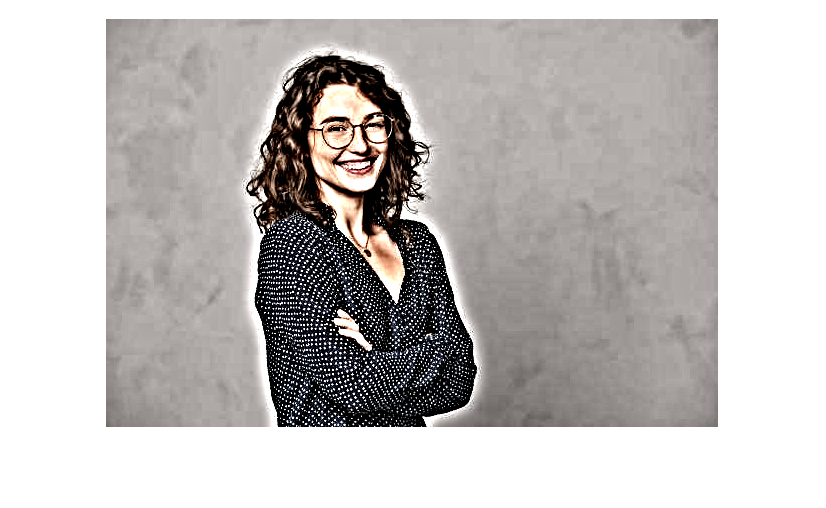

% Modify the coefficients if necessary (e.g., apply thresholding)


reconstructed_image1 = waverec2(c1,s1, wavelet2);
reconstructed_image2 = waverec2(c2,s2, wavelet2);
reconstructed_image3 = waverec2(c3,s3, wavelet2);

im_all_wavelet2 = zeros(size(reconstructed_image1));
im_all_wavelet2(:,:,1) = reconstructed_image1;
im_all_wavelet2(:,:,2) = reconstructed_image2;
im_all_wavelet2(:,:,3) = reconstructed_image3;

figure
title('reconstruct image')
imshow(uint8(im_all_wavelet2), [])

## Denoise

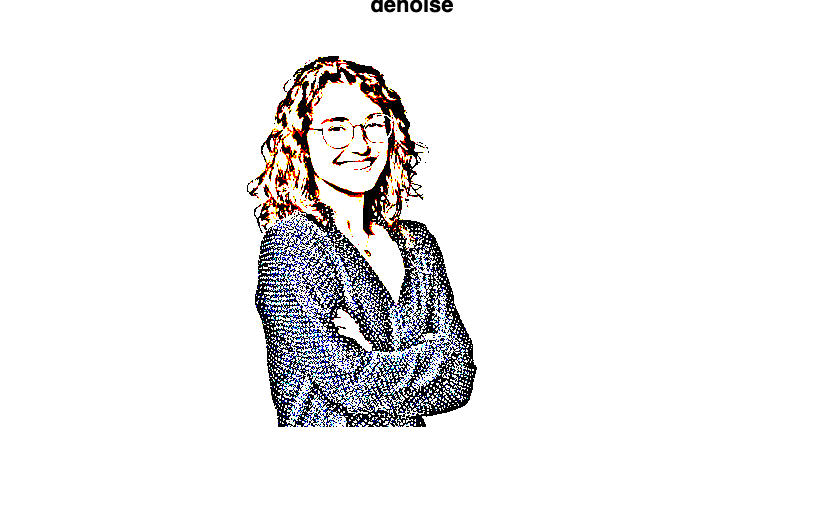

colorSpaceImage = rgb2ycbcr(im_all_wavelet2);

for i=1:3
    lumaChannel = colorSpaceImage(:, :, i);
    % Apply wavelet denoising to the luma channel
    denoisedLumaChannel = wdenoise2(lumaChannel, DenoisingMethod='Bayes');
    % Replace the denoised luma channel in the color space image
    colorSpaceImage(:, :, i) = denoisedLumaChannel;
end
% Convert the denoised color space image back to RGB
denoisedImage = ycbcr2rgb(colorSpaceImage);
imshow(denoisedImage, [])
title('denoise');

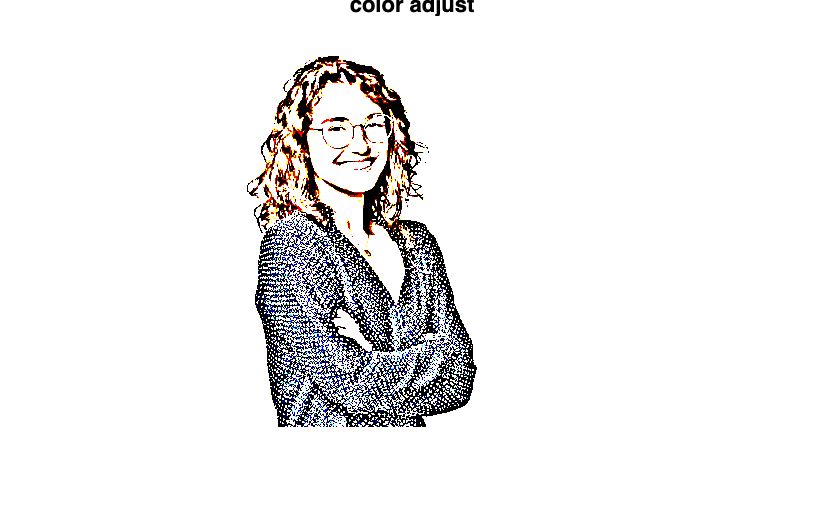

% color adjustment

% Apply color adjustments to change the color of the denoised image (e.g., increase red channel)
adjustedImage = denoisedImage;
adjustmentFactor = 5; % Adjust the factor based on your desired color change
adjustedImage = adjustedImage * adjustmentFactor; % Increase the red channel
figure
imshow(adjustedImage, [])
title('color adjust');

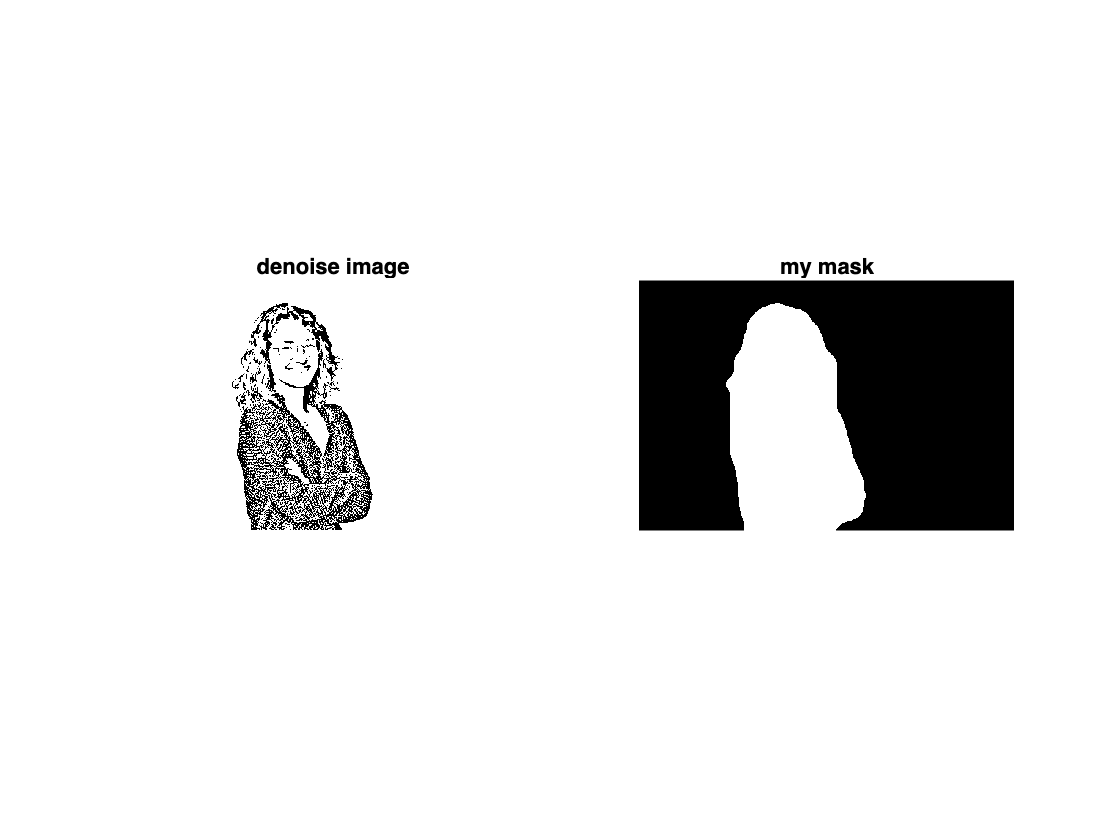

% histogram

[h_count1,h_cent1] = imhist(denoisedImage(:,:,1)./256);
h_prob1 = h_count1./numel(denoisedImage(:,:,1));
%figure
%bar(h_prob1)
%title('histogram of the denoise image')
figure
subplot(3,2,1)
imshow(denoisedImage(:,:,1), [])
title('denoise image')

modify = abs(1-denoisedImage(:,:,1));
subplot(3,2,2)
imshow(modify(:,:,1), [])
title('modify image')

im_fill=uint8(imfill(modify,26,'holes'));
im_fill2=uint8(imfill(im_fill,26,'holes'));
im_fill3=uint8(imfill(im_fill2,26,'holes'));
se = strel('disk',100);
im_close=imclose(im_fill3,se);

sigma=4;
im_mymask=imgaussfilt(im_close,sigma);

subplot(1,2,2)
imshow (im_mymask,[])
title('my mask')

## Get the mask

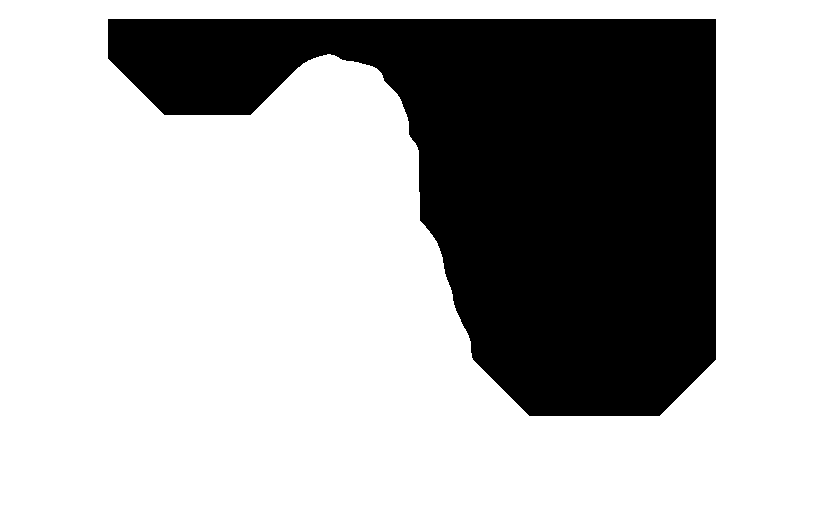

mask = filip_function(imname); 
figure
imshow(uint8(mask), [])

%resized_mask = imresize(mask, [228, 171]);

## Final

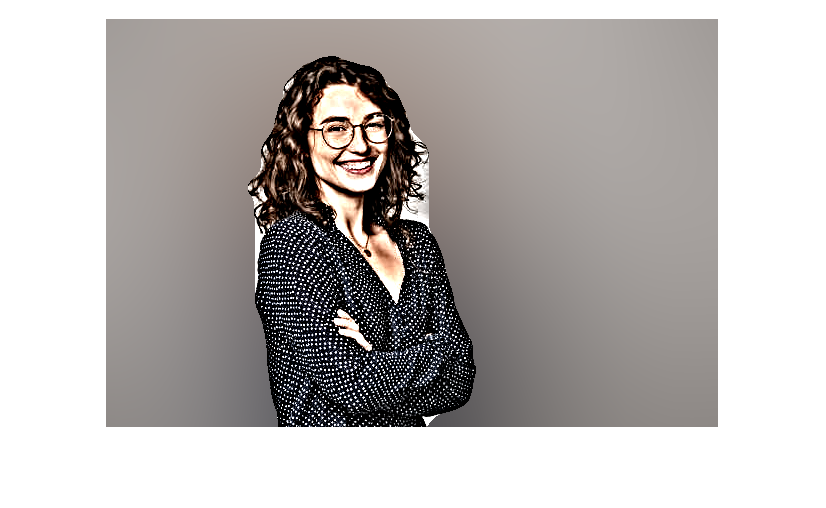


%im_all_og=double(imread(imname));
sigma=100;

%%
im_all_wavelet = im_all_wavelet2;
resized_mask = double(im_mymask); % mask
%%
background_blurred_all=zeros(size(im_all_wavelet));
im_new_all=zeros(size(im_all_wavelet));
me_all=zeros(size(im_all_wavelet));

%bg blurring
for i=1:3
    background_blurred = imgaussfilt(im_all_wavelet(:,:,i),sigma);
    im_new=background_blurred;

    me=im_all_wavelet(:,:,i).*resized_mask; 

    im_new(resized_mask==1.) = me(resized_mask==1.);
    im_new_all(:,:,i)=im_new;
end
    

figure()
imshow(uint8(im_new_all))